# Seismic Facies Classification Training Script 

#### Load the training data 

load data_train.mat

Error using load
Cannot read file \\mathworks\worldwide\US-Natick\hub\scratch\amishra\Facies classification\data_train.mat.

load labels_train.mat; 

data = double(data); 
labels = categorical(labels);

% Visualize the data with overlayed labels using the Volume Segmenter app 
volumeSegmenter(data, labels)

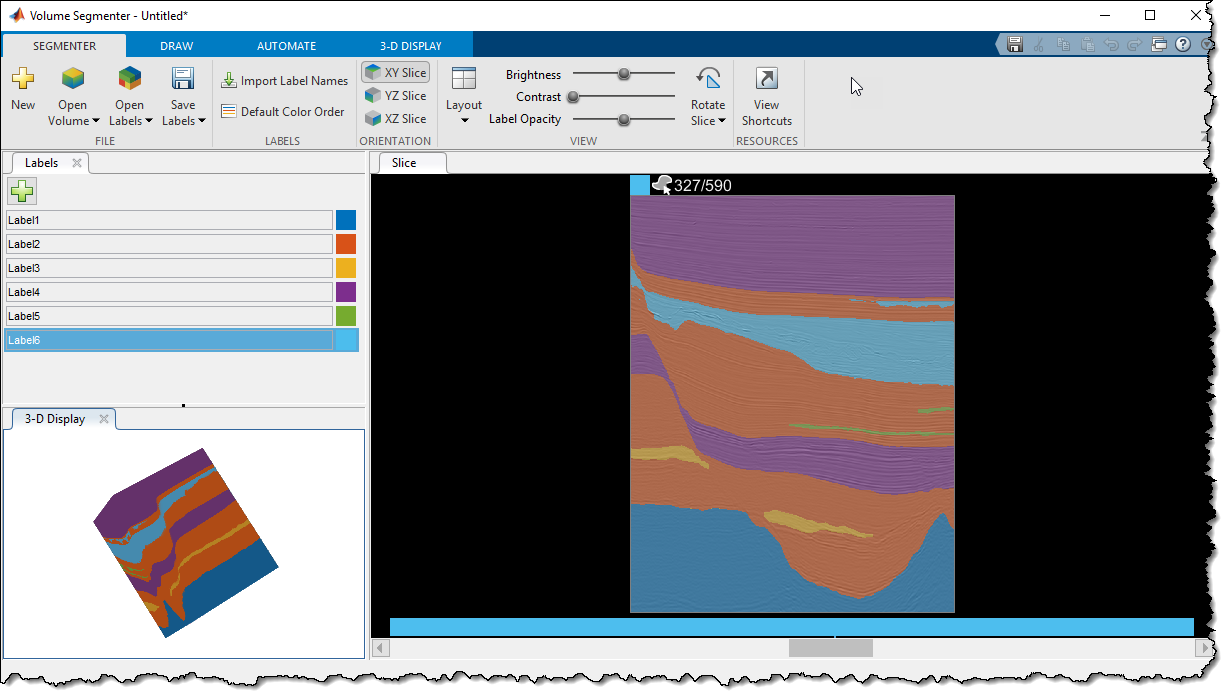

#### Extract 5 levels of maximal overlap discrete wavelet tranform features from each trace 

dataMRA = zeros([size(data),5]); 
parfor ii = 1 : 782
    for jj = 1:590
      dataMRA(:,ii,jj,:) = modwt(data(:,ii,jj), 'fk14',4)'; 
    end
end
clear data
dataMRA = single(dataMRA); 

#### Reshape the data to training sets after grouping them in 3x3 grid 

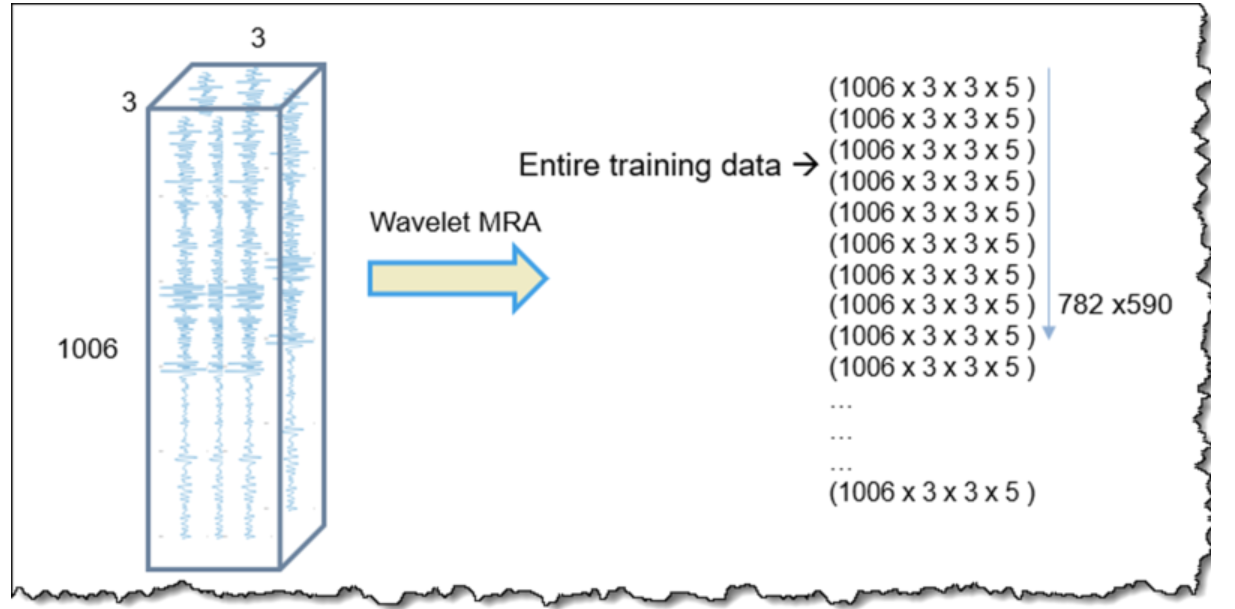

dataTrain = cell(782*590,1);
labelsTrain = cell(782*590,1);  
c=1; 
for ii = 2: 782-1 
    for jj = 2:590-1 
      tempData = permute((dataMRA(:,ii-1:ii+1, jj-1:jj+1, :)), [1 4 2 3]); 
      dataTrain(c,1) = {reshape(tempData, [1006 45])'} ; 
      labelsTrain(c,1) = {labels(:,ii,jj)'}; 
      c=c+1; 
    end
end

dataTrain = dataTrain(1:c-1); 
labelsTrain = labelsTrain(1:c-1); 
clear tempData


#### Divide the data into training, validation and testing set 

Note : You can replace the testing data with the data you have downloaded as well.  

testId = round(0.7*c); % 70% for training
valId = round(0.1*c); % 10% for validation 20% for testing 

idx = randperm(size(dataTrain,1)); % randomly shuffling the traces 


trainData = dataTrain(idx(1:testId)); 
valData = dataTrain(idx(testId+1: testId+valId)); 
testData = dataTrain(idx(testId+valId+1: end)); 

trainLabel= labelsTrain(idx(1:testId)); 
valLabel = labelsTrain(idx(testId+1: testId+valId)); 
testLabel= labelsTrain(idx(testId+valId+1: end)); 

clear dataTrain labelsTrain

#### Construct the RNN Network using biLSTM layers 

Additional class weigths have been assigned to facies with more relevance 

inputSize = [45]; 
numHiddenUnits1 = 50;
numHiddenUnits2 = 50;
numClasses = 6;

classWeights = [1 1 1 2 8 8]; 

lstmNet = [ ...
    sequenceInputLayer(inputSize,'Name','InputLayer',...
        'Normalization','zerocenter')
    bilstmLayer(numHiddenUnits1,'Name','bilstm1','OutputMode','sequence')
    layerNormalizationLayer('Name','LayerNormalization1')
    bilstmLayer(numHiddenUnits2,'Name','bilstm2')
    layerNormalizationLayer('Name','LayerNormalization2')
    fullyConnectedLayer(numClasses,'Name','FullyConnected')
    softmaxLayer('Name','smax');
    classificationLayer('Name','ClassificationLayer','Classes', {'1', '2', '3', '4', '5', '6'},'ClassWeights',classWeights)];


#### Define the training options and execute the training 

maxEpochs = 5; 
miniBatchSize = 15;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','auto', ...
    'L2Regularization',1e-3,...
    'InitialLearnRate',1e-3, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch',...
    'Verbose',0,...
    'ValidationFrequency', 1e4, ...
    'Plots','training-progress' );

[netLstm,infoGRU] = trainNetwork(trainData,trainLabel,lstmNet,options);

% Save the network in a .mat file 
save('netLstm.mat', 'netLstm'); 

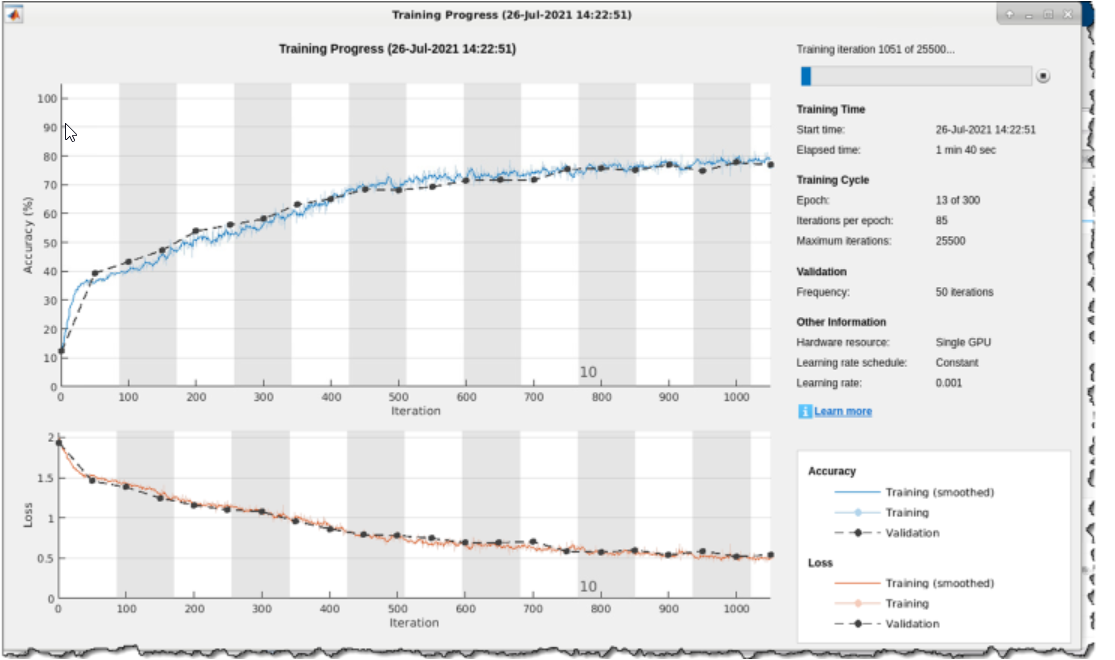

#### Evaluate the classification accuracy with confusion matrix on test data 

Ypred = classify(netLstm,testData);  
figure
confusionchart([Ypred{:}],[testLabel{:}],'Normalization','column-normalized');

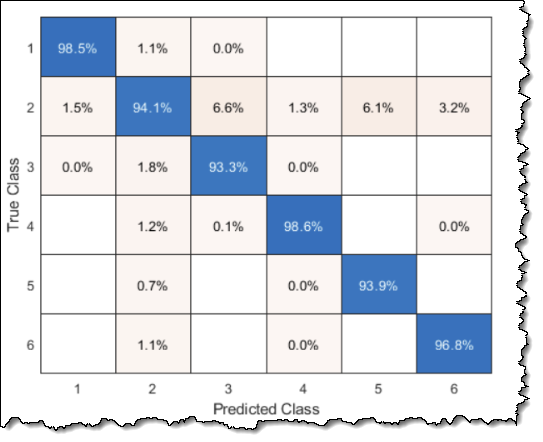

#### Call the classification function to get the labelled matrix 

% Load the testing data you might have downloaded 
yLabels = RNNClassificationTesting(testData); 

%Visualize the test data and the labels using Volume Viewer App. 
volumeViewer(testData, yLabels)